# Prva meritev 1,5 GHz filtra

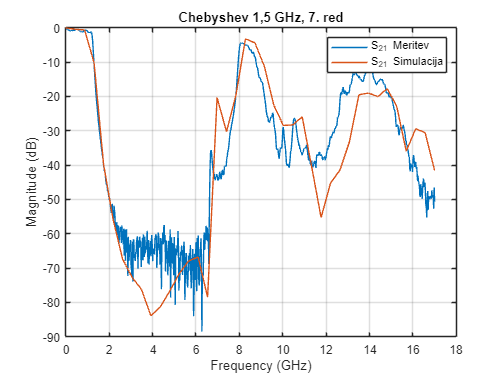

clc
clear all
close all

meas_15_init = sparameters("test2/sito_1-5GHz_7stopnje.S2P");
sim_15_init = sparameters("filtlow7.s2p");

% Overlay plot
figure
rfplot(meas_15_init, 2, 1)
hold on
rfplot(sim_15_init, 2, 1)
hold off
legend('S_{21} Meritev', 'S_{21} Simulacija')
title('Chebyshev 1,5 GHz, 7. red')

# Prva meritev 5 GHz filtra

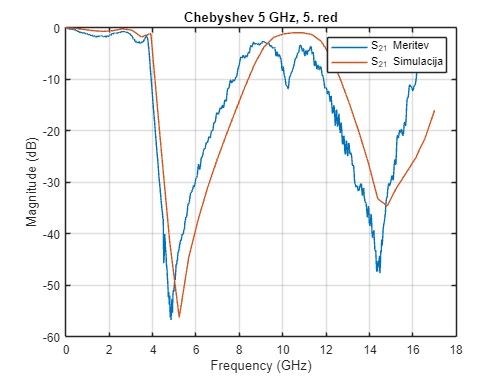

meas_5_init = sparameters("test2/sito_5GHz_5stopnje.S2P");
sim_5_init = sparameters("filthigh5theory.s2p");

% Overlay plot
figure
rfplot(meas_5_init, 2, 1)
hold on
rfplot(sim_5_init, 2, 1)
hold off
legend('S_{21} Meritev', 'S_{21} Simulacija')
title('Chebyshev 5 GHz, 5. red')

# Končna meritev 1,5 GHz filtra

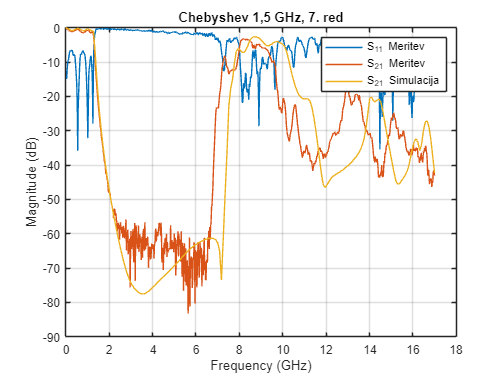

meas_15 = sparameters('test3/meritve/2_1_5G_7red.s2p');
sim_15 = sparameters('test3/iter2/filt_pg_low_2.s2p');

% Overlay plot
figure
rfplot(meas_15, 1, 1)
hold on
rfplot(meas_15, 2, 1)
hold on
rfplot(sim_15, 2, 1)
hold off
legend('S_{11} Meritev', 'S_{21} Meritev', 'S_{21} Simulacija')
title('Chebyshev 1,5 GHz, 7. red')

# Končna meritev 5 GHz filtra

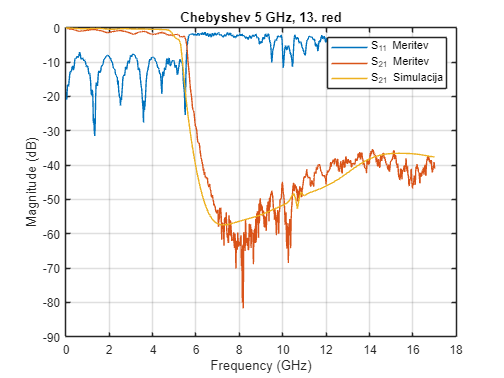

meas_5 = sparameters('test3/meritve/2_8G_13red.S2P');
sim_5 = sparameters('test3/iter2/filt_pg_hi.s2p');

% Overlay plot
figure
rfplot(meas_5, 1, 1)
hold on
rfplot(meas_5, 2, 1)
hold on
rfplot(sim_5, 2, 1)
hold off
legend('S_{11} Meritev', 'S_{21} Meritev', 'S_{21} Simulacija')
title('Chebyshev 5 GHz, 13. red')

# Meritev skupnega filtra

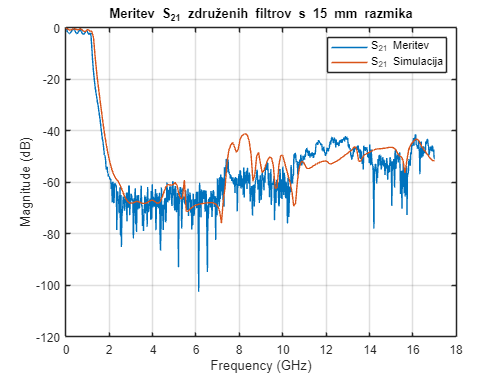

meas = sparameters('test3/meritve/2_full_15mm.S2P');
sim = sparameters('test3/iter2/filt_pg_full.s2p');

figure
rfplot(meas, 2, 1)
hold on
rfplot(sim, 2, 1)
hold off
legend('S_{21} Meritev', 'S_{21} Simulacija')
title('Meritev S_{21} združenih filtrov s 15 mm razmika')

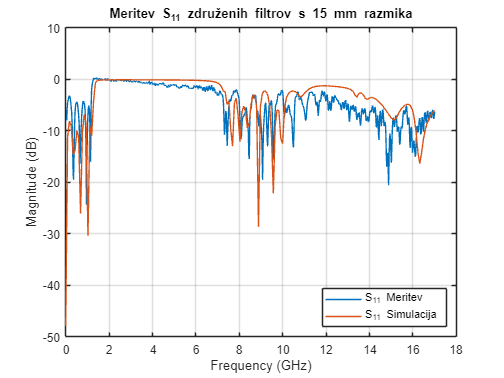

figure
rfplot(meas, 1, 1)
hold on
rfplot(sim, 1, 1)
hold off
legend({'S_{11} Meritev', 'S_{11} Simulacija'}, 'Location','southeast')
title('Meritev S_{11} združenih filtrov s 15 mm razmika')